## **A - Testing the Lifting Line Solver**

Hanchen Li (hl3422@ic.ac.uk)

### Test case 1

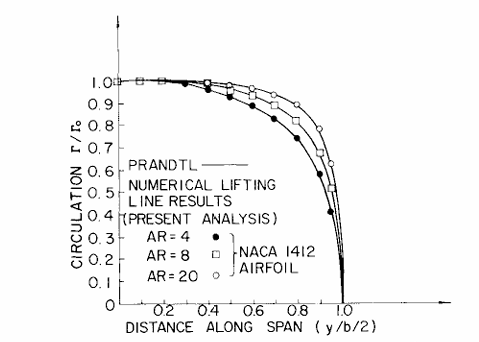

% Housekeeping
clear
clc
close all

% Basic parameters
U_inf = 50;        % freestream velocity (m/s)
c_0 = 1;           % chord length at middle of the span (m)
lambda = 1;        % taper ratio
a0 = 2 * pi;       % lift curve slope (per radian)
AoA = deg2rad(5);  % angle of attack (rad)
N = 500;           % number of wing section

for m = 1 : 3

b = 2 ^ (m + 1);   % span of the wing (m)

% Calculation
[CL, CDi, y, Gamma, c_values, alpha_i, iteration] = LLT(U_inf, c_0, lambda, b, a0, AoA, N);

% Result
fprintf('Case %d converged after %d iterations\n', m, iteration);
fprintf('Case %d lift coefficient: %.4f\n', m, CL);
fprintf('Case %d induced drag coefficient: %.6f\n', m, CDi);

% Store value
CL_total(m) = CL;

CDi_total(m) = CDi;

for p = 1 : length(Gamma)

    Gamma_total(m, p) = Gamma(p) ./ max(Gamma); % Normalise the result

    c_values_total(m, p) = c_values(p);

    alpha_i_total(m, p) = alpha_i(p);

end

end

Case 1 converged after 657 iterations


Case 1 lift coefficient: 0.3424


Case 1 induced drag coefficient: 0.010282


Case 2 converged after 783 iterations


Case 2 lift coefficient: 0.4136


Case 2 induced drag coefficient: 0.007890


Case 3 converged after 864 iterations


Case 3 lift coefficient: 0.4646


Case 3 induced drag coefficient: 0.005395


%%% Plotting
% Plot wing shape
figure(1)
clf;

plot(y, c_values_total(1, 1 : end), '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 2);
hold on

plot(y, c_values_total(2, 1 : end), '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 2);
hold on

plot(y, c_values_total(3, 1 : end), ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 2);
hold off

% Legends
legend("AR = 4", "AR = 8", "AR = 16", "Location",  "best", 'NumColumns', 1, FontSize = 11.5)

% Axis labels
xlabel('Spanwise Location (y)');
ylabel('Chord Length (c)');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

% Set plot grid
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 640 360]);
% Plot lift distribution along the span
figure(2)
clf;

plot(y, Gamma_total(1, 1 : end), '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 2);
hold on

plot(y, Gamma_total(2, 1 : end), '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 2);
hold on

plot(y, Gamma_total(3, 1 : end), ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 2);
hold off

% Legends
legend("AR = 4", "AR = 8", "AR = 16", "Location",  "best", 'NumColumns', 1, FontSize = 11.5)

% Axis labels
xlabel('Spanwise Location (y)');
ylabel('Circulation (Gamma)');
grid on;

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

% Set plot grid
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 640 360]);
% Plot induced angle distribution along the span
figure(3)
clf;

plot(y, rad2deg(alpha_i_total(1, 1 : end)), '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 2);
hold on

plot(y, rad2deg(alpha_i_total(2, 1 : end)), '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 2);
hold on

plot(y, rad2deg(alpha_i_total(3, 1 : end)), ':', 'Color', [139/255 69/255 19/255], 'LineWidth', 2);
hold off

% Legends
legend("AR = 4", "AR = 8", "AR = 16", "Location",  "best", 'NumColumns', 1, FontSize = 11.5)

% Axis labels
xlabel('Spanwise Location (y)');
ylabel('Induced Angle of Attack (degrees)');
grid on;

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

% Set plot grid
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 640 360]);

### Test case 2

% Housekeeping
clear
clc

% Basic parameters
U_inf = 5;         % freestream velocity (m/s)
c_0 = 1;           % chord length at middle of the span (m)
lambda = 1 / 3;    % taper ratio
b = 8;             % span of the wing (m)
a0 = 6;            % lift curve slope (per radian)
AoA = deg2rad(5);  % angle of attack (rad)
N = 500;           % number of wing section

% Calculation
[CL, CDi, y, Gamma, c_values, alpha_i, iteration] = LLT(U_inf, c_0, lambda, b, a0, AoA, N);

% Result
fprintf('Converged after %d iterations\n', iteration);

Converged after 585 iterations


fprintf('Lift coefficient: %.4f\n', CL);

Lift coefficient: 0.4425


fprintf('Induced drag coefficient: %.6f\n', CDi);

Induced drag coefficient: 0.005737


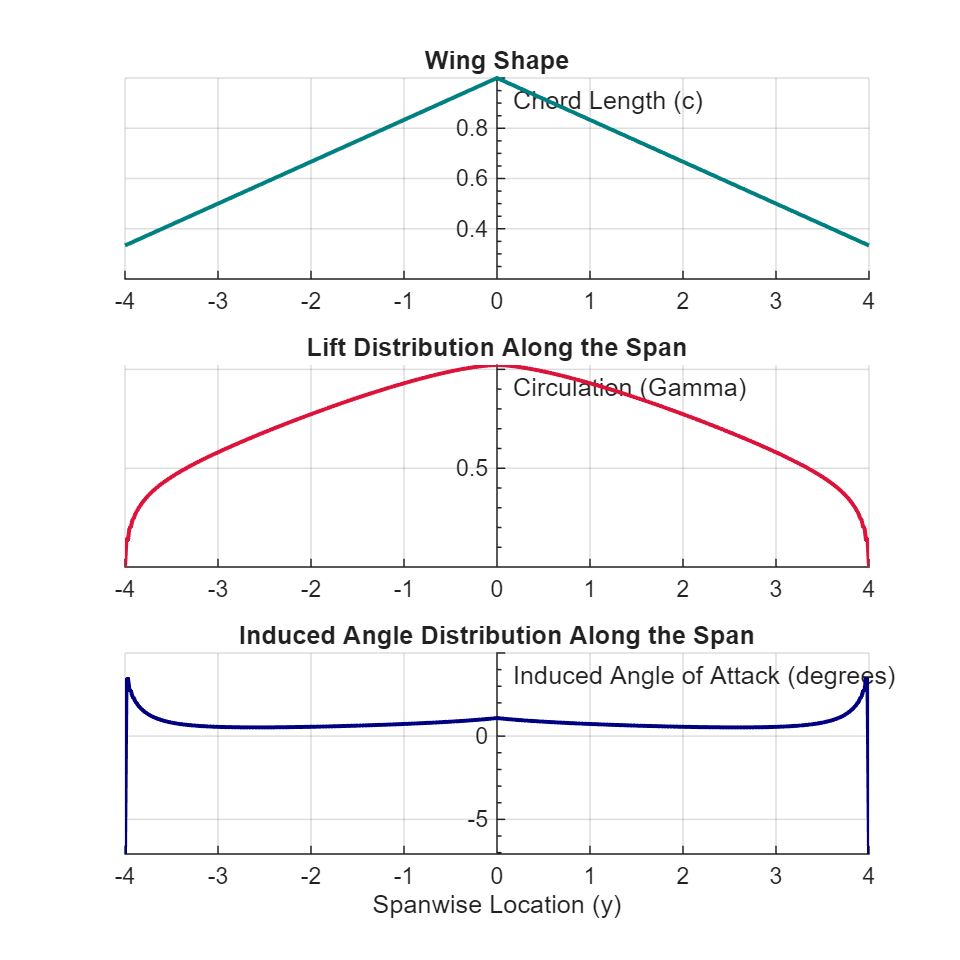


% Plot wing shape, lift distribution, and induced angle distribution
figure(4)
clf;

%%% Plotting
% Plot wing shape
subplot(3, 1, 1);
plot(y, c_values, '-', 'Color', [0/255 128/255 128/255], 'LineWidth', 2);
% xlabel('Spanwise Location (y)');
ylabel('Chord Length (c)');
title('Wing Shape');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
% ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

% Set plot grid
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Plot lift distribution along the span
subplot(3, 1, 2);
plot(y, Gamma, '-', 'Color', [220/255 20/255 60/255], 'LineWidth', 2);
% xlabel('Spanwise Location (y)');
ylabel('Circulation (Gamma)');
title('Lift Distribution Along the Span');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
% ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

% Set plot grid
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Plot induced angle distribution along the span
subplot(3, 1, 3);
plot(y, rad2deg(alpha_i), '-', 'Color', [0/255 0/255 128/255], 'LineWidth', 2);
xlabel('Spanwise Location (y)');
ylabel('Induced Angle of Attack (degrees)');
title('Induced Angle Distribution Along the Span');

% Customize axis appearance
set(gca, 'FontSize', 11.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'bottom';
ax.YAxisLocation = 'origin';
ax.YTickMode = 'auto';
ax.YMinorTick = 'on';
ax.LineWidth = 0.75;
ax.Box = 'off';

% Set plot grid
grid on;
ax.MinorGridLineStyle = '-'; 
ax.YMinorGrid = 'off'; 

% Set figure size
set(gcf, 'Position', [0 0 640 640]);

### Principle

This is a guess-and-correct method for solving the non-linear loading equation


$$\Gamma \left(y_1 \right)=\frac{1}{2}U_{\infty } c\left(y_1 \right)a_0 \left(y_1 \right)\alpha_e =\frac{1}{2}U_{\infty } c\left(y_1 \right)a_0 \left(y_1 \right)\left\lbrack \alpha \left(y_1 \right)-\frac{1}{4\pi U_{\infty } }\int_{-s}^{+s} \frac{\frac{d\Gamma }{\textrm{dy}}\textrm{dy}}{y_1 -y}\right\rbrack$$


where $s$ is half wing span

### **1. Divide wing**

Divide wing into a number of spanwise stations

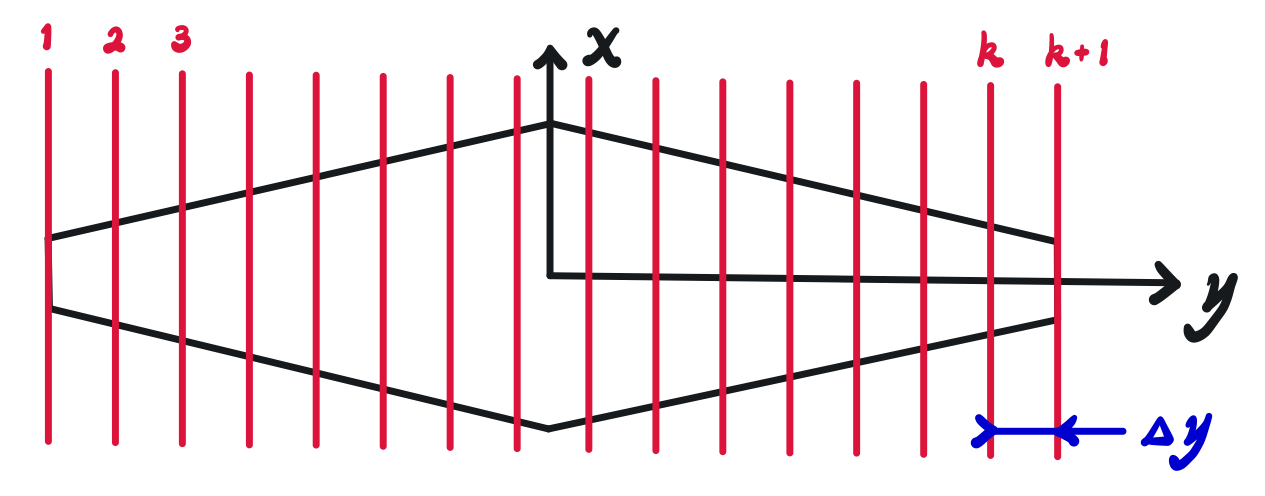

here k + 1 stations are shown

### **2. Guess distribution of for **$\Gamma$

For the given wing at given $\alpha$, assume the lift distribution along the span

i.e. assume value for $\Gamma$ at all stations, $\Gamma_1$,$\Gamma_2$, $\Gamma_3$, ..., $\Gamma_k$, $\Gamma_{k+1}$

(An elliptical lift distribution is satisfactory for such an assumed distribution)

#### **2.1. Compute **$\alpha_i$


$$\alpha_i \left(y_n \right)=\frac{1}{4\pi U_{\infty } }\int_{-s}^{+s} \frac{\frac{d\Gamma }{\textrm{dy}}}{y_n -y}\textrm{dy}$$


**Simpson Rule **$\alpha_i \left(y_n \right)=\frac{1}{4\pi U_{\infty } }\frac{\Delta y}{3}\sum_{j=2,4,6,\ldotp \ldotp \ldotp }^k \left\lbrack \frac{{\left(\frac{d\Gamma }{\textrm{dy}}\right)}_{j-1} }{y_n -y_{j-1} }+4\frac{{\left(\frac{d\Gamma }{\textrm{dy}}\right)}_j }{y_n -y_j }+\frac{{\left(\frac{d\Gamma }{\textrm{dy}}\right)}_{j+1} }{y_n -y_{j+1} }\right\rbrack$

N.B. Singularties (e.g. $y_n =$$y_{j-1}$, $y_n =$$y_j$ or $y_n =$$y_{j+1}$) correted by replacing the given term by its average value based on the two adjacent sections

where $\frac{d\Gamma }{\textrm{dy}}$ can be compute as other numerical gradient

e.g. central differencing scheme

#### **2.2. Obtain **$\alpha_e$


$$\alpha_e \left(y_n \right)=\alpha \left(y_n \right)-\alpha_i \left(y_n \right)$$


### **3. Iteration**

#### **3.1. Obtain **${\left(C_L \right)}_n$

Obtain Sectional Lift Coefficient ${{C_L }^{\prime } }_n$ at each station from the know lift curve for the aerofoil

i.e. ${\left(C_L \right)}_n =a_0 \left(y\right)\alpha_e \left(y\right)$

#### **3.2. Calculate **$\Gamma \left(y_n \right)$**  from **${\left(C_L \right)}_n$


$$L^{\prime } \left(y_n \right)=\rho U_{\infty } \Gamma \left(y_n \right)=\frac{1}{2}\rho {U_{\infty } }^2 c_n {\left(C_L \right)}_n$$


Therefore, ${\Gamma \left(y_n \right)}_{\textrm{result}} =\frac{1}{2}U_{\infty } c_n {\left(C_L \right)}_n$

where is $c_n$ local section chord

#### **3.3. Iteration**

if $\left|{\Gamma \left(y_n \right)}_{\textrm{result}} -{\Gamma \left(y_n \right)}_{\textrm{input}} \right|\prec \epsilon$


$${\Gamma \left(y_n \right)}_{\textrm{input}} =$$

$${\Gamma \left(y_n \right)}_{\textrm{input}} +D\left\lbrack {\Gamma \left(y_n \right)}_{\textrm{result}} -{\Gamma \left(y_n \right)}_{\textrm{input}} \right\rbrack$$


where $D$ is damping factor

### **4. Compute Result**


$$C_L =\frac{2}{U_{\infty } S}\int_{-s}^{+s} \Gamma \left(y\right)\textrm{dy}$$



$$C_{D_i } =\frac{2}{U_{\infty } S}\int_{-s}^{+s} \Gamma \left(y\right)\alpha_i \left(y\right)\textrm{dy}$$


These can again be carried out by Simpson's rule

where $S=2s\bar{\mathrm{c}}$ and $\bar{\mathrm{c}}$ is average chord length